##  МИУ

close all;
clear variables;

Входные параметры

%  1 - входные данные 
k0 = 2*pi;
% Параметры среды-1
e1 = 2.89;
mu1 = 1;
k1 = k0*sqrt(mu1*e1);
eta1 = 120*pi*sqrt(mu1/e1);

% Параметры среды-2
k2 = k0;
eta2 = 120*pi;

% Параметры программы
N = 100; % количество точек на круга
% полуоси элипса

a = 3.8/pi; % вертикаль (РАЗМЕР)
b = a; % горизонталь (РАЗМЕР)

phi_i_grad = 225; % угол падения [град]
phi_i_rad = 2*pi/360*phi_i_grad; % угол падения [рад]
gamma = 1.781072417990;

% ========================================================================
%  Построение круга
dphi_grad = 360/N; % угловой шаг на круга [град]
dphi_rad =  2*pi/360*dphi_grad; % угловой шаг на круга [рад]

% % круга в полярной системе координат (пусть будет)
% % получение векторов углов и вектора ридиусов
% phi_circl_rad = zeros(1, N);
% phi_circl_grad = zeros(1, N);
% a_for_graph = zeros(1, N);
% for i = 1 : N
%     phi_circl_rad(i) = (i-1)*dphi_rad + dphi_rad/2;
%     phi_circl_grad(i) = (i-1)*dphi_grad + dphi_grad/2;
%     a_for_graph(i) = a;
% end

Генервция dx

dx_b = b/N;
dx_a = a/N;

Генерация точек


% генератора координат для первого участка
dx_mass = zeros(1, 4*N);
for n= 1 : N
    % горизонт 1
    x1(n) = (n-0.5)*dx_b;
    z1(n) = 0;
    % вертикаль 1
    x2(n) = b;
    z2(n) = (n-0.5)*dx_a;
    % горизонт 2
    x3(n) = (n-0.5)*dx_b;
    z3(n) = a;
    % вертикаль 2
    x4(n) = 0;
    z4(n) = (n-0.5)*dx_a;  
    
    % сразу заполним dx
    dx_mass(n) = dx_b;
    dx_mass(n+N) = dx_a;
    dx_mass(n+2*N) = dx_b;
    dx_mass(n+3*N) = dx_a;
end

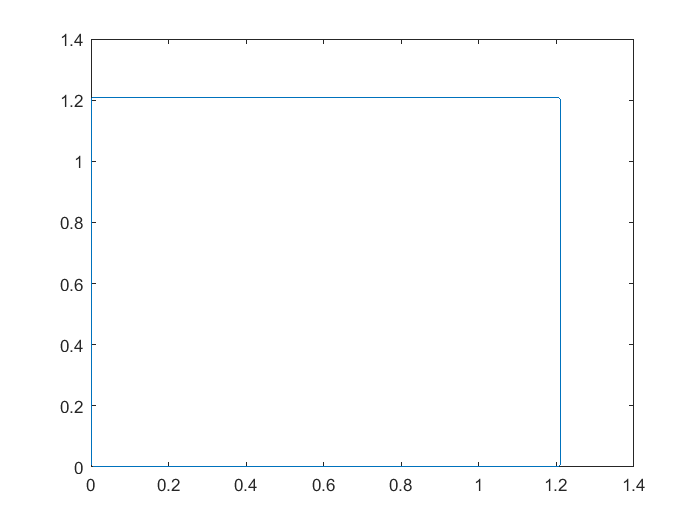

% координта на поверхности цилиндра
x_midle = [x1 x2 fliplr(x3) x4];
z_midle = [z1 z2 z3 fliplr(z4)];

plot(x_midle,z_midle)

Расчет касательных к отрезкам разибения

% касательные * до копирования
tx_one = [-1 0 1 0];
tz_one = [0 -1 0 1];

%  общие касательный
tz = [repmat(tz_one(1),1,N) repmat(tz_one(2),1,N) repmat(tz_one(3),1,N) repmat(tz_one(4),1,N)];
tx = [repmat(tx_one(1),1,N) repmat(tx_one(2),1,N) repmat(tx_one(3),1,N) repmat(tx_one(4),1,N)];

Посчитаем n для каждого отрезка

%   нормальный вектор найдем с помощью матрицы повороты
    alpha = -90;
    matrix = [cosd(alpha),-sind(alpha); sind(alpha),cosd(alpha)];

for i = 1 : 4*N
     matrix_temp = [tx(i), tz(i)]*matrix;
     nx(i) = matrix_temp(1);
     nz(i) = matrix_temp(2);
end

% plot(tx(2),tz(2))
% compass([nx(1),nz(1)])

% ========================================================================
% 3 - cам ходя расчета 
% списик для хранения элементов системы 
Z = zeros(8*N,8*N);
Y = zeros(8*N,8*N);
    
for m  = 1 : 4*N
    xm = x_midle(m);
    zm = z_midle(m);
    txm = tx(m);
    tzm = tz(m);
    nxm = nx(m);
    nzm = nz(m);
    
    for n = 1 : 4*N
        xn = x_midle(n);
        zn = z_midle(n);
        txn = tx(n);
        tzn = tz(n);
        nxn = nx(n);
        nzn = nz(n);
        dx = dx_mass(n);
            
        % Растояние между началом координат О2 и точкой наблюдений (в ГСК)        
        x_mO2 = xm - xn;
        z_mO2 = zm - zn;
        
        % Положим этот вектор на новую СК
        % Координаты этой точки (в ЛСК)
        umn = x_mO2*txn + z_mO2*tzn;
        wmn = x_mO2*nxn + z_mO2*nzn;
        
        
        % локальные замены 
        xmn = xm - xn;
        zmn = zm - zn;
        r = sqrt(xmn^2 + zmn^2);
        
        umn_plus = umn + dx/2;
        umn_minus = umn - dx/2; 
        r_minus = sqrt(umn_minus^2 + wmn^2);
        r_plus = sqrt(umn_plus^2 + wmn^2);
        rmn = sqrt(umn^2 + wmn^2);
        
        if n == m
            % электрическое поле
            E1y = -k1*eta1*dx*1/4*(1 + 1i*2/pi*(log(gamma*k1*dx/4)-1));
            E2y = -k2*eta2*dx*1/4*(1 + 1i*2/pi*(log(gamma*k2*dx/4)-1));
            
            % магнитное поле
            H1u = -1/2;
            H2u = +1/2;
            H1w = 0;
            H2w = 0;
            
        elseif abs(n-m) <= -1.5
        
            % электрчиеское поле
            E1y = k1*dx + k1*2*1i/pi * (wmn*(atan(umn_plus/wmn) - atan(umn_minus/wmn))...
            + umn_plus*log(gamma*k1/2*sqrt(umn_plus^2+wmn^2))...
            - umn_minus*log(gamma*k1/2*sqrt(umn_minus^2+wmn^2)) - dx);
            E1y = -E1y * eta1 * 1/4;

            E2y = k2*dx + k2*2*1i/pi * (wmn*(atan(umn_plus/wmn) - atan(umn_minus/wmn))...
            + umn_plus*log(gamma*k2/2*sqrt(umn_plus^2+wmn^2))...
            - umn_minus*log(gamma*k2/2*sqrt(umn_minus^2+wmn^2)) - dx);
            E2y = -E2y * eta2 * 1/4;
            
            % магнитное поле 
            H1u = 1i/8*wmn*k1^2*dx + 1/(2*pi)*(atan(umn_plus/wmn) - atan(umn_minus/wmn)); % 
            H2u = 1i/8*wmn*k2^2*dx + 1/(2*pi)*(atan(umn_plus/wmn) - atan(umn_minus/wmn)); % delta?
            
            H1w = 1i/4*(H(0,k1*r_plus) - H(0,k1*r_minus));
            H2w = 1i/4*(H(0,k2*r_plus) - H(0,k2*r_minus));
        else
            % электрчиеское поле
            E1y = -k1*eta1*1/4*dx*H(0,k1*rmn); % delta?
            E2y = -k2*eta2*1/4*dx*H(0,k2*rmn); % delta?
               
            % магнитное поле     
            H1u = 1i/4*k1*dx*(wmn/rmn*H(1,k1*rmn)); % delta?
            H2u = 1i/4*k2*dx*(wmn/rmn*H(1,k2*rmn)); % delta?
            
            H1w = 1i/4*(H(0,k1*r_plus) - H(0,k1*r_minus));
            H2w = 1i/4*(H(0,k2*r_plus) - H(0,k2*r_minus));
        end
        % элементы системы       
        E1mn = E1y;
        E2mn = -E2y;
        
        dot_tm_tn = (txm*txn+tzm*tzn);
        dot_tm_nn = (txm*nxn+tzm*nzn);
        
        H1mn = dot_tm_tn*H1u + dot_tm_nn*H1w;
        H2mn = -(dot_tm_tn*H2u + dot_tm_nn*H2w);
        
        % запись в массив для дальнешего решения 
        Z(m,n) = E1mn;
        Z(m,n+4*N) = E2mn;
        Z(m+4*N,n) = H1mn;
        Z(m+4*N,n+4*N) = H2mn;
    end
end

E = zeros(4*N,1);
% падающее поле 
for m = 1 : 4*N
    xm = x_midle(m);
    zm = z_midle(m);
    txm = tx(m);
    tzm = tz(m);

    % cоставляющие полей
    cx = -1i*k2*cosd(phi_i_grad);
    cz = -1i*k2*sind(phi_i_grad);
    
    Eiy = exp(cx*xm+cz*zm);
    Hix = 1/eta2*sind(phi_i_grad) * Eiy;
    Hiz = -1/eta2*cosd(phi_i_grad) * Eiy;
    
    % элементы системы  
    Ei = Eiy;
    Hi = txm*Hix + tzm*Hiz;

    % запись в массив для дальнешего решения 
    E(m) = Ei;
    E(m+4*N) = Hi;
end    

% Расчитаем токи
% тут зашито сразу 2 тока
I = Z\E;

% отделим один ток от другого
j1 = I(1:4*N);
j2 = I(4*N+1:8*N);

Сделаем счетчик для графика в градусах

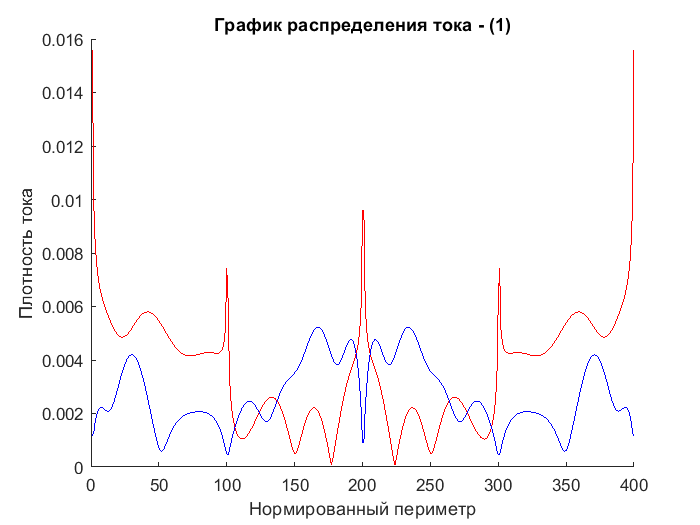

% номера ВИ для графика 
n_for_graf = zeros(1, 4*N);
for i = 1 : 4* N
     n_for_graf(i) = i;
end

% построение графика респределения токов в ВИ

% ось X в относительных единицах
figure;
hold on;
plot(n_for_graf, abs(j1), 'r');
plot(n_for_graf, abs(j2), 'b');
title('График распределения тока - (1)'); 
xlabel('Нормированный периметр'); 
ylabel('Плотность тока');
hold off;

## ЭПР

for p = 1 : 721
    Sum_E = 0;
    phi = (p-1)/2; % угол из формулы для приведения 721 к 360 градусам
    phi_for_graf_DA(p) = (p-1)/2; % угол для графика
    
    cx = - 1i*k2*cosd(phi);
    cz = - 1i*k2*sind(phi);
    

        for n = 1 : 4*N
            txn = tx(n);
            tzn = tz(n);
            xn = x_midle(n);
            zn = z_midle(n);
            dx = dx_mass(n);
            
            Sum_E = Sum_E + eta2*k2/4*dx*j2(n)*exp(cx*xn+cz*zn);      
        end
    
    RCS(p) = 10*log10((4/k2)*Sum_E*conj(Sum_E));
%     RCS(p) = 2*sqrt(2*pi*((4/k2)*Sum_E*conj(Sum_E)));


end

% график поля в дальней зоне от угла налюденя (не нормированный)
figure;
plot(phi_for_graf_DA, RCS,'r-');

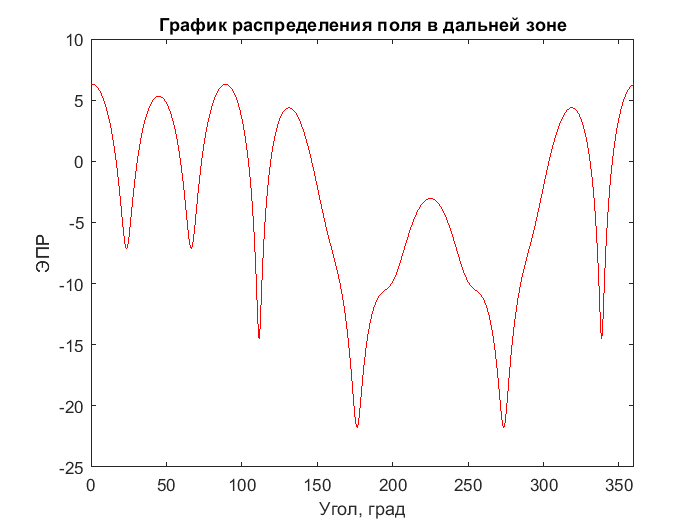

title('График распределения поля в дальней зоне'); 
xlim([0 360])
xlabel('Угол, град'); 
ylabel('ЭПР');

Электрическое Поле на поврехности 

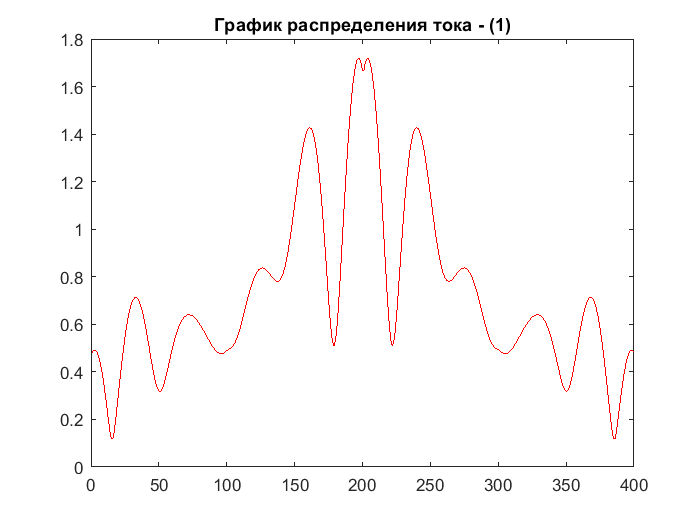

E_surf = zeros(4*N, 1); 
for m  = 1 : 4*N
    xm = x_midle(m);
    zm = z_midle(m);
    txm = tx(m);
    tzm = tz(m);
    nxm = nx(m);
    nzm = nz(m);
    
    E_surf_n = 0;
    for n = 1 : 4*N
        xn = x_midle(n);
        zn = z_midle(n);
        txn = tx(n);
        tzn = tz(n);
        nxn = nx(n);
        nzn = nz(n);
        dx = dx_mass(n);
            
        % Растояние между началом координат О2 и точкой наблюдений (в ГСК)        
        x_mO2 = xm - xn;
        z_mO2 = zm - zn;
        
        % Положим этот вектор на новую СК
        % Координаты этой точки (в ЛСК)
        umn = x_mO2*txn + z_mO2*tzn;
        wmn = x_mO2*nxn + z_mO2*nzn;
        
        % локальные замены 
        xmn = xm - xn;
        zmn = zm - zn;
        r = sqrt(xmn^2 + zmn^2);
        
        umn_plus = umn + dx/2;
        umn_minus = umn - dx/2; 
        r_minus = sqrt(umn_minus^2 + wmn^2);
        r_plus = sqrt(umn_plus^2 + wmn^2);
        rmn = sqrt(umn^2 + wmn^2);   
        
        if n == m
            % электрическое поле
            E2y = -k2*eta2*dx*1/4*(1 + 1i*2/pi*(log(gamma*k2*dx/4)-1));
              
        elseif abs(n-m) <= -1.5
            % электрчиеское поле
            E2y = k2*dx + k2*2*1i/pi * (wmn*(atan(umn_plus/wmn) - atan(umn_minus/wmn))...
            + umn_plus*log(gamma*k2/2*sqrt(umn_plus^2+wmn^2))...
            - umn_minus*log(gamma*k2/2*sqrt(umn_minus^2+wmn^2)) - dx);
            E2y = -E2y * eta2 * 1/4;

        else
            % электрчиеское поле
            E2y = -k2*eta2*1/4*dx*H(0,k2*rmn); % delta?
        end
        
        E_surf_n = E_surf_n + j2(n) * E2y;
    end
    
    E_surf(m) =  E_surf_n; 
 end
 
 
figure;
plot(n_for_graf, abs(E_surf), 'r');
title('График распределения тока - (1)'); 

### Вывод данных для графиков

% name_file = strcat('I_MIE_circl_diel_Epol_j1_', num2str(N),'.dat');
% f01 = fopen(name_file,'w');
% 
% % за максимум Y примем значения в центре передней стороны падения
% 
% for n=1:N
%     fprintf(f01,' %10.5f %10.5f\n', phi_circl_grad(n), abs(j1(n)));
% end
% 
% fclose(f01);

% name_file = strcat('I_MIE_circl_diel_Epol_j2_', num2str(N),'.dat');
% f02 = fopen(name_file,'w');
% 
% % за максимум Y примем значения в центре передней стороны падения
% 
% for n=1:N
%     fprintf(f02,' %10.5f %10.5f\n', phi_circl_grad(n), abs(j2(n)));
% end
% 
% fclose(f02);

% name_file = strcat('DA_MIE_circl_diel_Epol_j2_', num2str(N),'.dat');
% f03 = fopen(name_file,'w');
% 
% % за максимум Y примем значения в центре передней стороны падения
% 
% for n= 1 : 721
%     fprintf(f03,' %10.5f %10.5f\n', phi_for_graf_DA(n), RCS(n));
% end
% 
% fclose(f03);

function [H_calc] = H(n,x)
    H_calc = besselh(n,1,x); 
end

function [J_calc] = J(n,x)
    J_calc = besselJ(n,x); 
end
    
function [dJ_calc] = dJ(n,x)
    dJ_calc = n/x*besselj(n,x) - besselj(n+1,x);
end

function [dH_calc] = dH(n,x)
    dH_calc = n/x*besselh(n,1,x) - besselh(n+1,1,x);
end